## Succession SPL patterns

Calculating SPL patterns with various low frequency ranges to account for anthronoise on JJTug

Generate plot using pcolor with SPL in specific frequency bands for each 15 min segment to show daily and seasonal patterns in an easy to understand and compare format

The output is saved to then investigate the difference between temporal patterns. Once the frequency ranges are finalized, these scripts can be combined. 

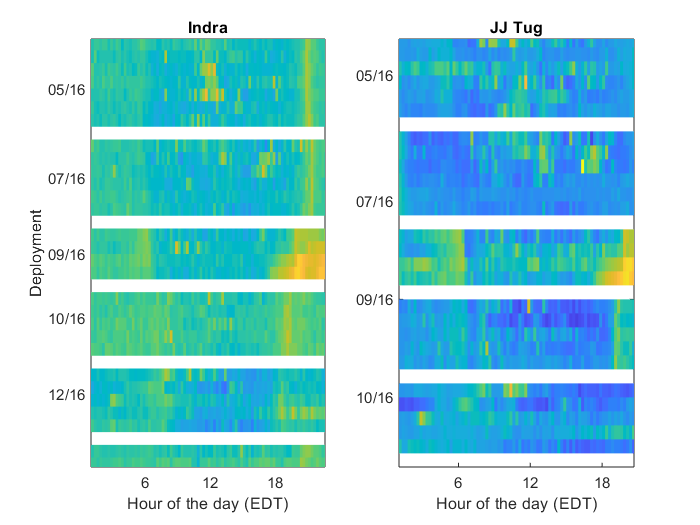

clear
load('trimmed_resultsNO20.mat');

tbins=0:0.25:23.75;
low = find(freqlist>=150 & freqlist<=2000);
high = find(freqlist>=7000 & freqlist<= 15000);
%high = find(freqlist>=3000 & freqlist<= 15000);


% Indra D1
low_Id1 = NaN(7,96);
high_Id1 = NaN(7,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtI1 == tbins(i)); 
    low_Id1(:,i) = sum(Indra_1_poavg(low,a));
    high_Id1(:,i) = sum(Indra_1_poavg(high,a));
end

%Indra D2
low_Id2 = NaN(6,96);
high_Id2 = NaN(6,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtI2 == tbins(i)); 
    low_Id2(:,i) = sum(Indra_2_poavg(low,a));
    high_Id2(:,i) = sum(Indra_2_poavg(high,a));
end

%Indra D3 
%low_Id3 = NaN(4,96);
%high_Id3 = NaN(4,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtI3 == tbins(i)); 
    low_Id3(:,i) = sum(Indra_3_poavg(low,a));
    high_Id3(:,i) = sum(Indra_3_poavg(high,a));
end

%Indra D4
low_Id4 = NaN(5,96);
high_Id4 = NaN(5,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtI4 == tbins(i)); 
    low_Id4(:,i) = sum(Indra_4_poavg(low,a));
    high_Id4(:,i) = sum(Indra_4_poavg(high,a));
end

% Indra D5
%low_Id5 = NaN(5,96);
%high_Id5 = NaN(5,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtI5 == tbins(i)); 
    low_Id5(:,i) = sum(Indra_5_poavg(low,a));
    high_Id5(:,i) = sum(Indra_5_poavg(high,a));
end

% Indra D6
%low_Id6 = NaN(6,96);
%high_Id6 = NaN(6,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtI6 == tbins(i)); 
    low_Id6(:,i) = sum(Indra_6_poavg(low,a));
    high_Id6(:,i) = sum(Indra_6_poavg(high,a));
end

% JJTug D1
%low_Jd1 = NaN(8,96);
%high_Jd1 = NaN(8,96);

for i = 1:length(tbins) 
    a = find(hrmn_edtJ1 == tbins(i)); 
    low_Jd1(:,i) = sum(JJTug_1_poavg(low,a));
    high_Jd1(:,i) = sum(JJTug_1_poavg(high,a));
end

% JJTug D2
%low_Jd2 = NaN(8,96);
%high_Jd2 = NaN(8,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtJ2 == tbins(i)); 
    low_Jd2(:,i) = sum(JJTug_2_poavg(low,a));
    high_Jd2(:,i) = sum(JJTug_2_poavg(high,a));
end

% JJTug D3
%low_Jd3 = NaN(4,96);
%high_Jd3 = NaN(4,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtJ3 == tbins(i)); 
    low_Jd3(:,i) = sum(JJTug_3_poavg(low,a));
    high_Jd3(:,i) = sum(JJTug_3_poavg(high,a));
end

% JJTug D4
%low_Jd4 = NaN(8,96);
%high_Jd4 = NaN(8,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtJ4 == tbins(i)); 
    low_Jd4(:,i) = sum(JJTug_4_poavg(low,a));
    high_Jd4(:,i) = sum(JJTug_4_poavg(high,a));
end

% JJTug D5
%low_Jd5 = NaN(5,96);
%high_Jd5 = NaN(5,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtJ5 == tbins(i)); 
    low_Jd5(:,i) = sum(JJTug_5_poavg(low,a));
    high_Jd5(:,i) = sum(JJTug_5_poavg(high,a));
end

% JJTug D6
%low_Jd6 = NaN(8,96);
%high_Jd6 = NaN(8,96);
for i = 1:length(tbins) 
    a = find(hrmn_edtJ6 == tbins(i)); 
    low_Jd6(:,i) = sum(JJTug_6_poavg(low,a));
    high_Jd6(:,i) = sum(JJTug_6_poavg(high,a));
end

save SPL_NO20_150Hz_7_15kHz.mat low_Id1 high_Id1 low_Jd1 high_Jd1 low_Id2 high_Id2 low_Jd2 high_Jd2 low_Id3 high_Id3 low_Jd3 high_Jd3 low_Id4 high_Id4 low_Jd4 high_Jd4 low_Id5 high_Id5 low_Jd5 high_Jd5 low_Id6 high_Id6 low_Jd6 high_Jd6
%save SPL_NO20_150Hz_2_15kHz.mat low_Id1 high_Id1 low_Jd1 high_Jd1 low_Id2 high_Id2 low_Jd2 high_Jd2 low_Id3 high_Id3 low_Jd3 high_Jd3 low_Id4 high_Id4 low_Jd4 high_Jd4 low_Id5 high_Id5 low_Jd5 high_Jd5 low_Id6 high_Id6 low_Jd6 high_Jd6


%clear 
%load("SPL_NO20_150Hz_7_20kHz.mat");
%% Prepping and Plotting

nan_sep = NaN(1,96);
tbins = 0:.25:23.75;

% Low Frequency
low_Indra_all = [low_Id1;nan_sep;low_Id2;nan_sep;low_Id3;nan_sep;low_Id4;nan_sep;low_Id5;nan_sep;low_Id6];
low_JJTug_all = [low_Jd1;nan_sep;low_Jd2;nan_sep;low_Jd3;nan_sep;low_Jd4;nan_sep;low_Jd5;nan_sep;low_Jd6];

figure; set(gcf,'units','centimeters','position',[0,0,16.9,6]);
subplot(1,2,1);pcolor(tbins,1:38,10*log10(low_Indra_all));caxis([80,125]);title('Indra');ylabel('Deployment');xlabel('Hour of the day (EDT)');shading flat;set(gca,'ydir','reverse');
xticks([0:6:18]); xticklabels([0:6:18]);
yticks([5 12 18 23 29 35]);yticklabels({'05/16','07/16','09/16','10/16','12/16','04/17'});
subplot(1,2,2);pcolor(tbins,1:38,10*log10(low_JJTug_all));caxis([80,125]);title('JJ Tug');xlabel('Hour of the day (EDT)');shading flat;set(gca,'ydir','reverse');
xticks([0:6:18]); xticklabels([0:6:18]);
yticklabels({});%yticks([5 14 21 28 35 43]);

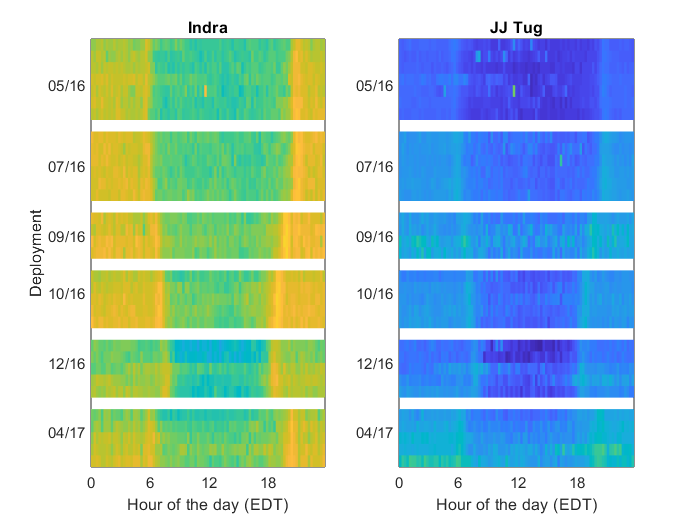

savefig(gcf,"temporal_patterns_150-2000Hz.fig")

% High Frequency
high_Indra_all = [high_Id1;nan_sep;high_Id2;nan_sep;high_Id3;nan_sep;high_Id4;nan_sep;high_Id5;nan_sep;high_Id6];
high_JJTug_all = [high_Jd1;nan_sep;high_Jd2;nan_sep;high_Jd3;nan_sep;high_Jd4;nan_sep;high_Jd5;nan_sep;high_Jd6];

figure; set(gcf,'units','centimeters','position',[0,0,16.9,6]);
subplot(1,2,1);pcolor(tbins,1:38,10*log10(high_Indra_all));caxis([95,130]);title('Indra');ylabel('Deployment');xlabel('Hour of the day (EDT)');shading flat;set(gca,'ydir','reverse');
xticks([0:6:18]); xticklabels([0:6:18]);
yticks([5 12 18 23 29 35]);yticklabels({'05/16','07/16','09/16','10/16','12/16','04/17'});
subplot(1,2,2);pcolor(tbins,1:38,10*log10(high_JJTug_all));caxis([95,130]);title('JJ Tug');xlabel('Hour of the day (EDT)');shading flat;set(gca,'ydir','reverse');
xticks([0:6:18]); xticklabels([0:6:18]);
yticklabels({});%yticks([5 12 18 23 29 35]);
savefig(gcf,"temporal_patterns_7-15kHz.fig")
